# Basic Image Enhancement and Analysis Techniques

This example shows how to enhance an image as a preprocessing step before analysis. The image used in this examlpe belonges to MathWorks image processing toolbox.

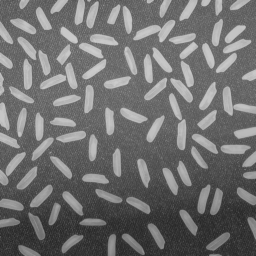

**rice.png**

**First**, the nonuniform background must be illuminated to deal only with foreground objects. **Secondly**, the image is converted into a binary format. **Thirdly**, many image-analysis may be performed like:

- Counting objects

- Identifying the smallest object among all the objects 

## Clear the workspace

clear variables;    % Remove variables from the workspace
clc;                % Delete messages from the command window

## First Step: Removing background

### Displaying the image

The image is a grayscale image. This means that each pixel ranges from 0 to 255. That's why $I$is $256\times 256$of class uint8.

cImagePath = 'Images\rice.png'; % The image path
I = imread(cImagePath);         % Load image
% imshow(I);                    % Uncommit this to display the image
% imInfo = imfinfo(cImagePath)  % Uncommit this to display image information

### Background approximation

The approximation of the background must follow, at its best, the background morphology: the backgroud is brighter at its center than at its edges. The image opening operation can be performed in such approximation. A structuring element is applied to each pixel of the image. It must be must be larger than the objects in the foreground (rices). More investigations on the opening operation and the structuring element can be found in  `mtb1_13_StructuringElem.mlx`.

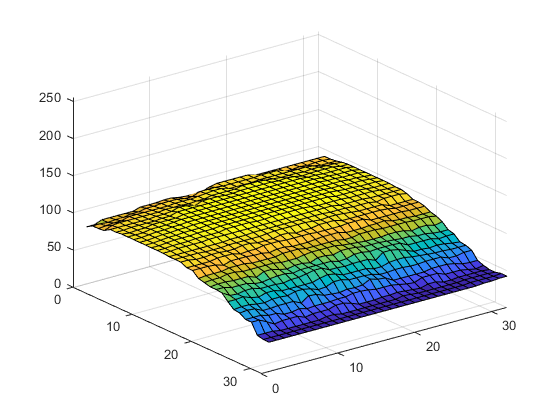

structElem = strel('disk',15);          % Building structuring element
background = imopen(I, structElem);     % Morphological opennig image
                                        % to approximate the background
% Check the quality of the background approximation
figure
leng
surf(double(background(1:8:end,1:8:end))),...
                        zlim([0 255]);  % Display background approximation in 3D
set(gca,'ydir','reverse');

% imshow(background);           % Uncommit this to display the background
                                % approximation

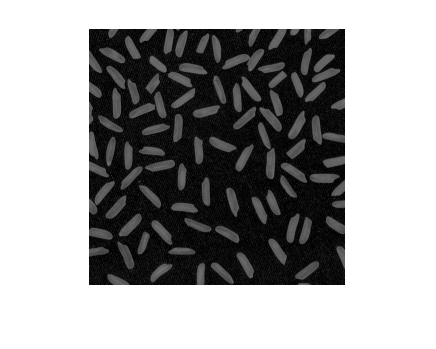

I2 = I - background;            % Remove the background approximation
                                % from the original image. Therefore,
                                % the backgroud of the resulting image
                                % is now likely more uniform.
imshow(I2)

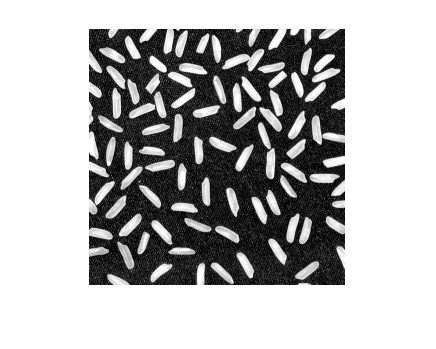

I3 = imadjust(I2);                  % Maps the intensity values in grayscale
                                    % image I2 to new values in I3. By default,
                                    % imadjust saturates the bottom 1% and the
                                    % top 1% of all pixel values.
imshow(I3);

## Second step: convert to a binary format

The convertion from a grayscale image to a binary image depends on a threshold. MATLAB uses Otsu's method in order to figure out the value of the threshold. Otsu's method chooses a threshold that minimizes the intraclass variance of the thresholded black and white pixels. To be noted that the threshold is normalized to the range [0, 1]. Also, an effectiveness metric of the threshold is returned as a nonnegative number in the range [0, 1]. The lower bound is attainable only by images having a single gray level, and the upper bound is attainable only by two-valued images. The function `graythresh` gives the threshold's value and its effectiveness metric. It is used automatically inside the conversion function `imbinarize`.

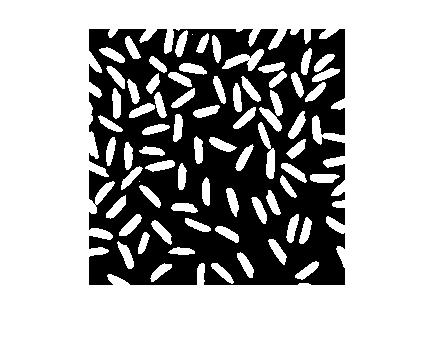

% [level, EM] = graythresh(I3);     % Uncommit this to display the value of
                                    % the threshold and its effectiveness
                                    % metric
bw = imbinarize(I3);
imshow(bw);

The converted image contains small dots that must be eliminated before any alalysis. Thus, we issue a command that eliminate all objects having less than 5 pixels. This operation is known as an *area opening*.

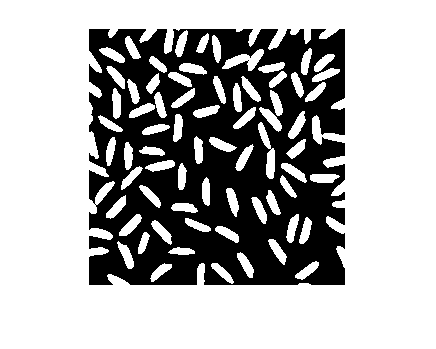

bw1 = bwareaopen(bw, 5);                % Remove objects having less than 5 pixels
imshow(bw1)

## Third step: Image analysis

### Counting objects

The image contains 101 distinct objects. MATLAB finds and counts connected components using `bwconncomp` function. An object must have all of its pixels connected. If the connectivity is 4, then the pixels edges touch. If the connectivity is 8, then the pixels edges or corners touch. In the present case, the function identifies 99 objects when connectivity is 4 and 97 objects when connectivity is 8. The current section explains the reasons behind such behavior. For the rest of this example, connectivity will be set to 4.

cc4 = bwconncomp(bw1, 4);               % Find objects with connectivity set to 4
cc8 = bwconncomp(bw1, 8);               % Find objects with connectivity set to 8

infoBB4 = regionprops(cc4, "BoundingBox");  % Get the bounding box for each object
                                        % (conn = 4)
imshow(bw1);                            % Display the image
hold on;                                % Hold on, new plots will be added
for i = 1:length(infoBB4)               % Put all objects inside a red rectangle
    rectangle("Position", infoBB4(i).BoundingBox, ...
        "LineWidth", 2, "EdgeColor", 'r');
end
infoBB8 = regionprops(cc8, "BoundingBox"); % Get the bounding box for each object
                                        % (conn = 8)
for i = 1:length(infoBB8)               % Put all objects inside a green rectangle
    rectangle("Position", infoBB8(i).BoundingBox, ...
        "LineWidth", 1, "EdgeColor", 'g');
end
hold off;

### Identifying the smallest object

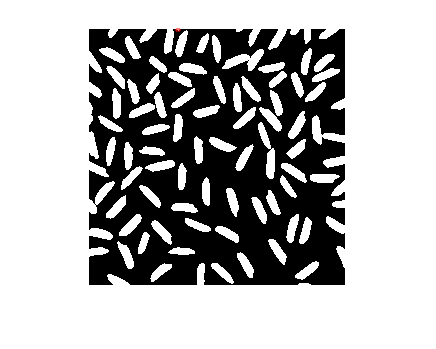

stats = regionprops(cc4, "Area", "BoundingBox");
objectArea = [stats.Area];
[~, indMinArea] = min(objectArea);
imshow(bw1);
hold on;
rectangle("Position", stats(indMinArea).BoundingBox,...
    "EdgeColor", 'r');
hold off;

% stats = regionprops(cc,'Area','Eccentricity'); 
% idx = find([stats.Area] > 80 & [stats.Eccentricity] < 0.8); 
% BW2 = ismember(labelmatrix(cc),idx); 


% imshow(I);